all_amino = [h_aminoacid;aminoacid];
length(all_amino)

ans = 23

ma = multialign(char(all_amino(:,1)))

ma = 23×604 char array
    '--------------------------------------------------M-----------------------------------------------------------------------------------ANLLLLIVPILIAMAFLMLTERKILGYMQLRKGPNVVGPYGLLQPFADAMKLFTKEPLKPATSTITLYITAPTLALTIALLLWTPLPMPNPLVNLNLGLLFILATSSLAVYSILWSGWASNSNYALIGALRAVAQTISYEVTLAIILLSTL---------------------------------LMSGSFNLSTLITTQEHLWLLLPSWPLAMMWFISTLAETNRTPFDLAEGESELVSGFNIEYAAGPFALFFMAEYTNIIMMNTLTTTIFLGTTYDALSPELYTTYFVTKTLLLTS---------------------------------------------------------------------------LFLWIRTAYPRFRYDQLMHLLWKNFLPLTLALLMWYVSMPITISSIPPQT*----------------------------------------------'
    'MNENLFASFIAPTILGLPAAVLI-------------------------------------------------------------------ILFPPLLIPTSKYLINNRLITTQQWLIKLTSKQMMTMHNTKGRTWSLMLVS---------------------------------------LIIFIATTNLLGLLPHSFTPTTQLSMNLAMAIPLWAGTVIMGFRSKIKNALAHFLPQGTPTPLIPMLVIIETISLLIQPMALAVRLTANI-------------------------------------------------------------------------------------------

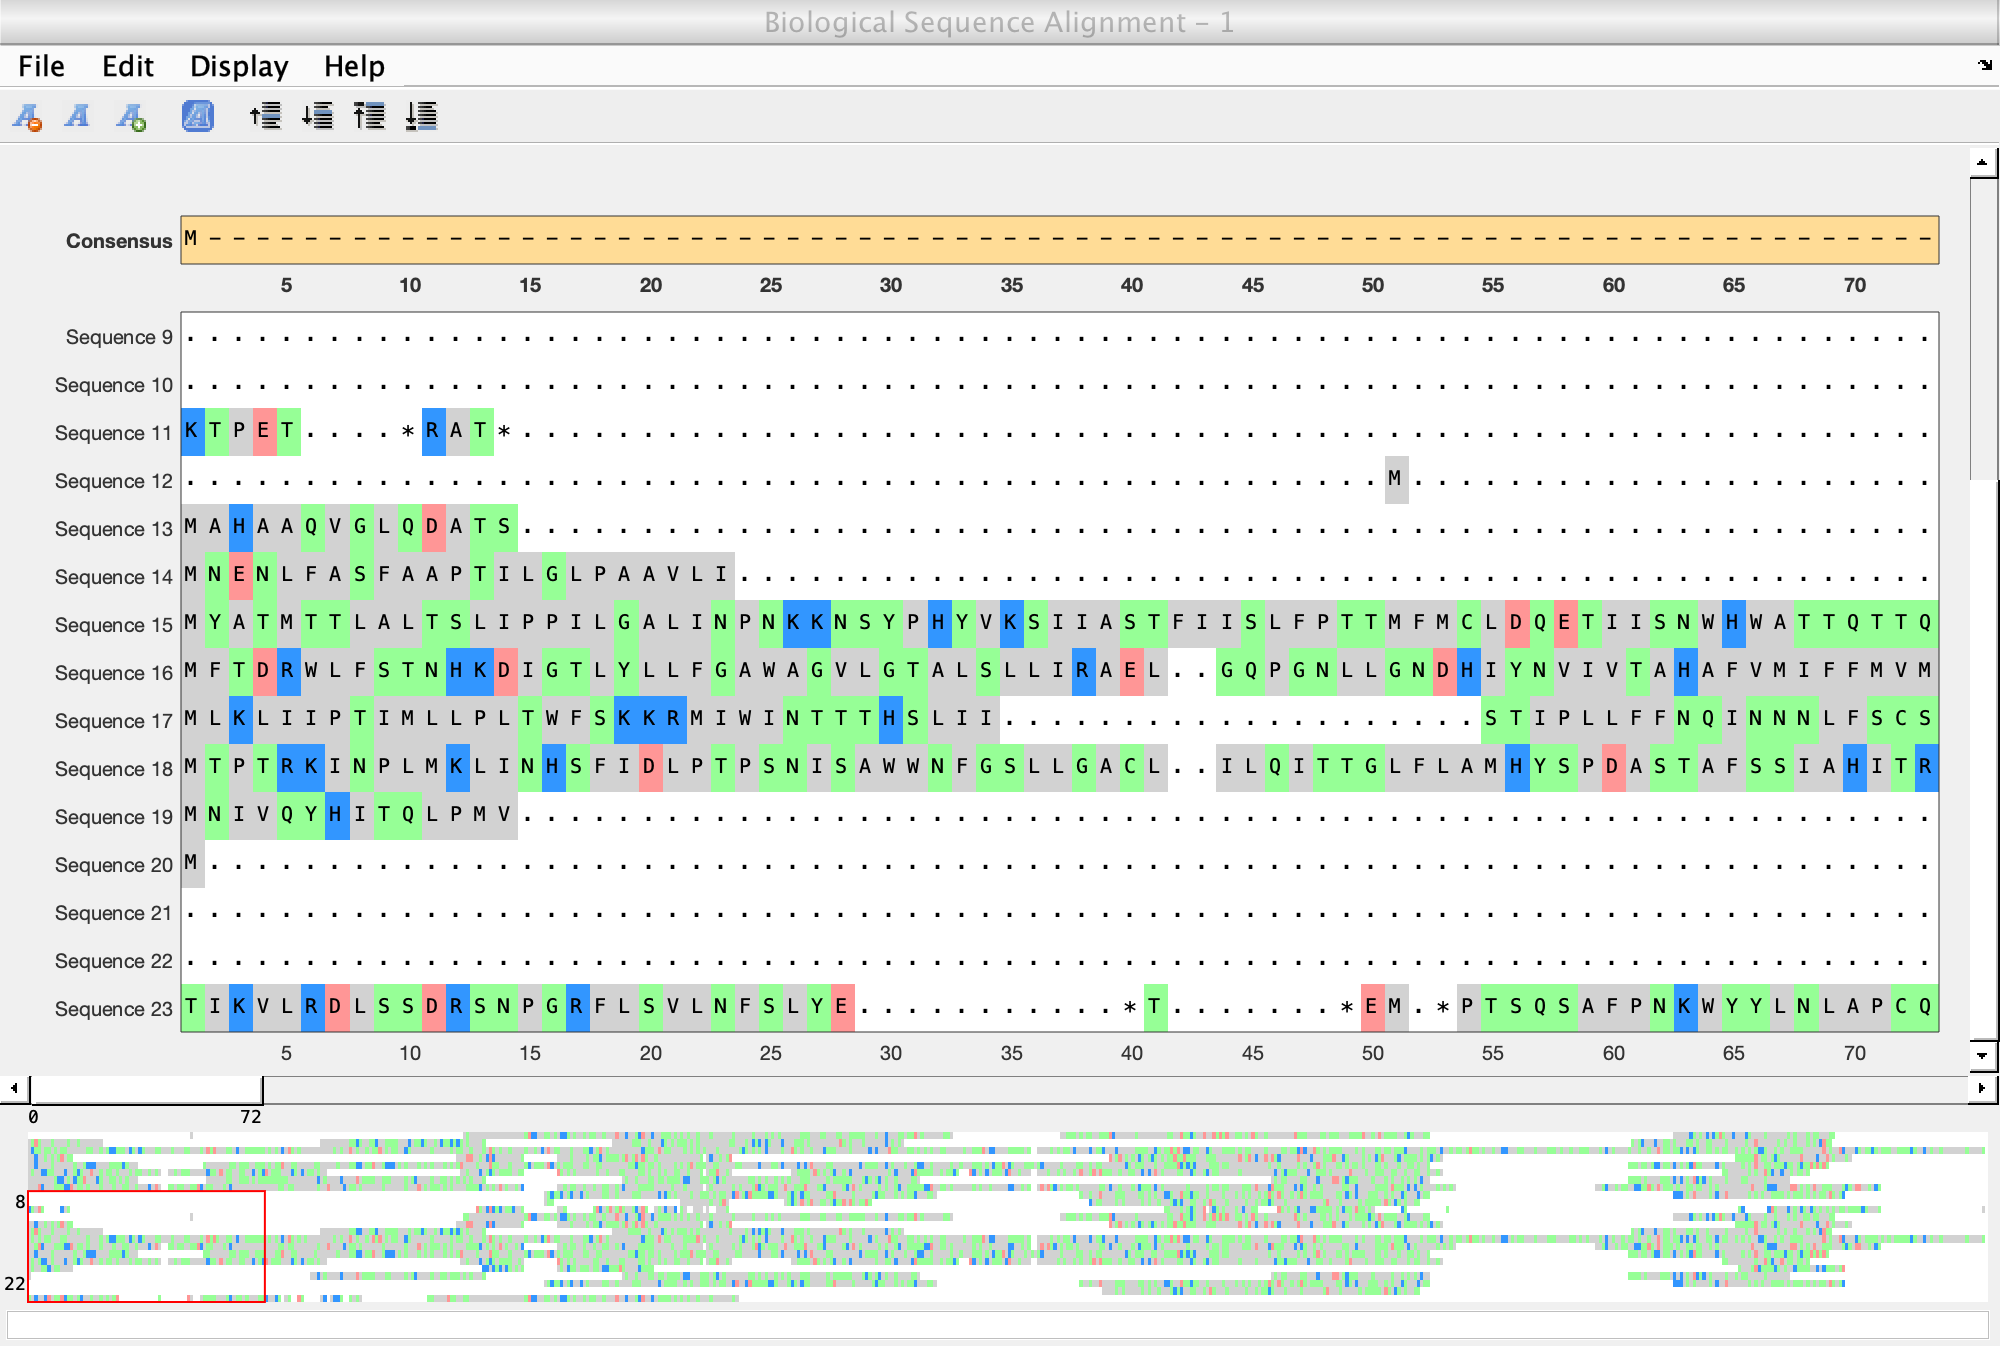

seqalignviewer(ma)

scores = [];
for i=1: length(h_aminoacid)
    for j=1:length(aminoacid)
        scores = [scores; i,j,nwalign(char(h_aminoacid(i,1)), char(aminoacid(j,1)), 'scoringmatrix','blosum30','gapopen',5,'extendgap',5)];
    end
end

length(scores)

ans = 132

tobetested = find(scores(:,3) > 100)

tobetested =      1
    15
    28
    38
    54
    67
    81
    89
   106


total_combinations = length(scores)

total_combinations = 110

length(char(h_aminoacid(1,1)))

ans = 317

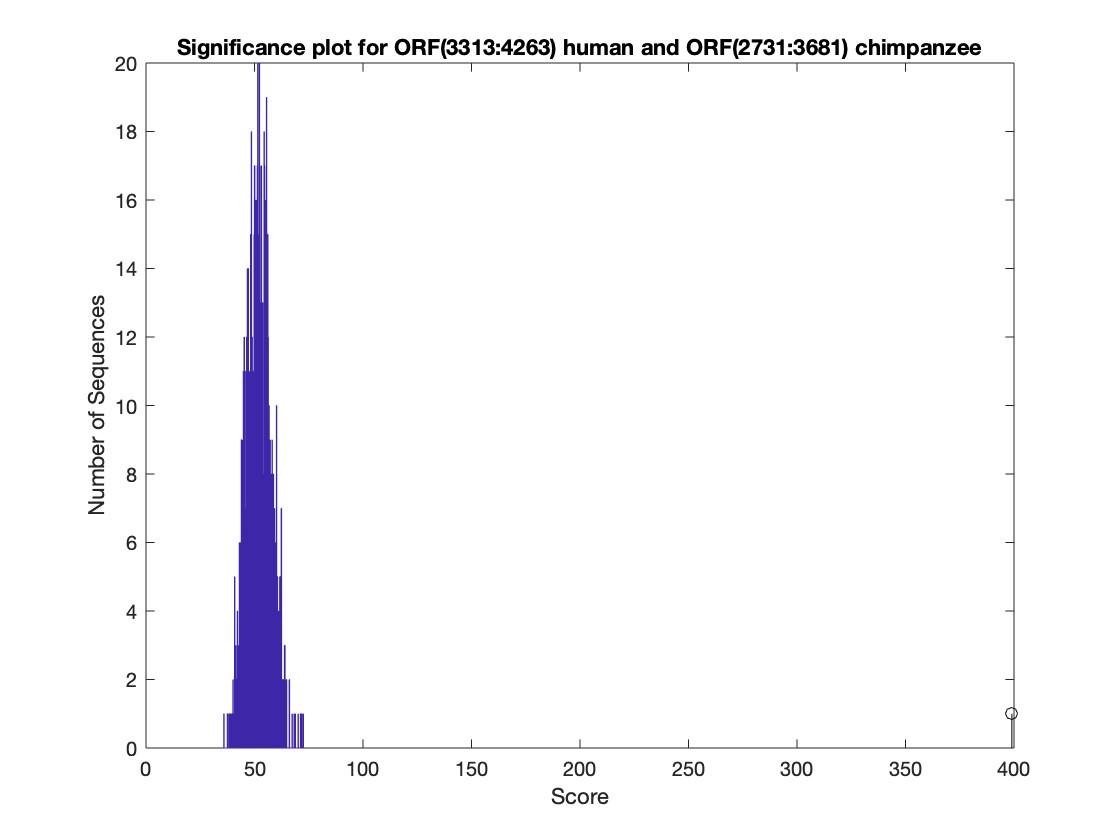

score = 399

p_value = 0

ans = "ORF in position(3313:4263) in human is homologous to ORF in position (2731:3681) in chimpanzee"

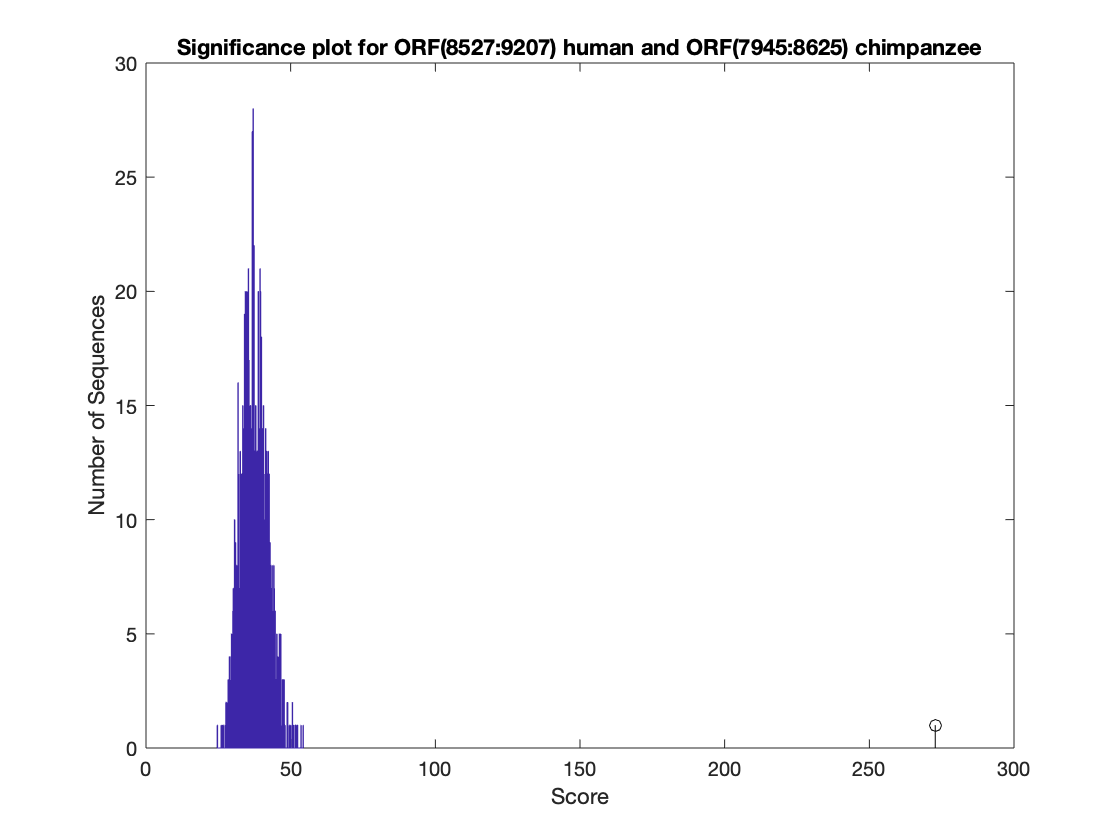

score = 272.8000

p_value = 0

ans = "ORF in position(8527:9207) in human is homologous to ORF in position (7945:8625) in chimpanzee"

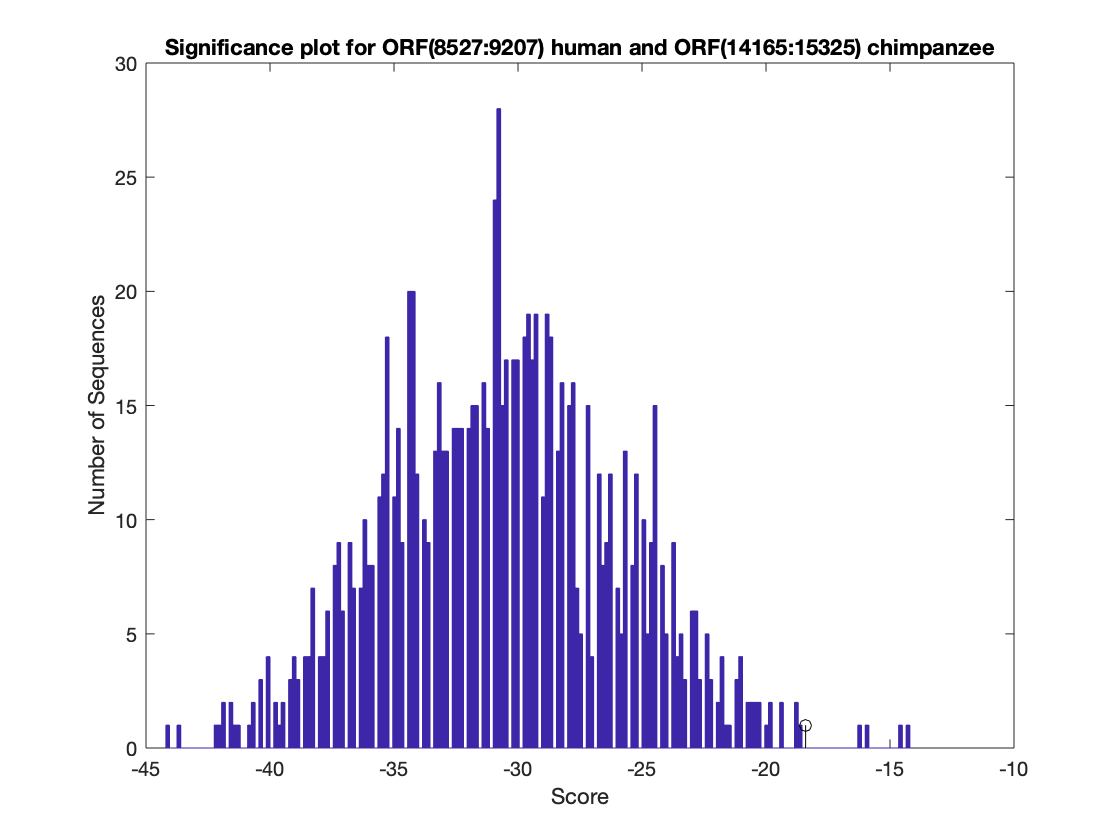

score = -18.4000

p_value = 0.0040

ans = "ORF in position(8527:9207) in human is homologous to ORF in position (14165:15325) in chimpanzee"

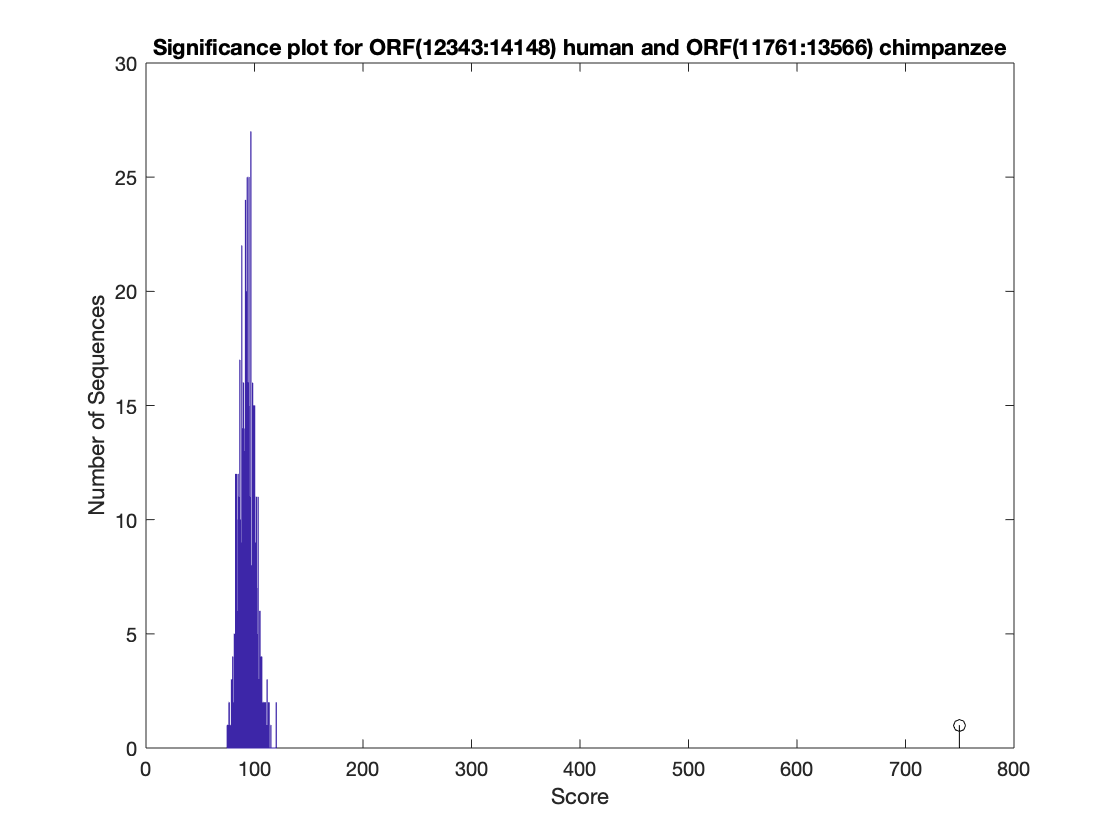

score = 749.6000

p_value = 0

ans = "ORF in position(12343:14148) in human is homologous to ORF in position (11761:13566) in chimpanzee"

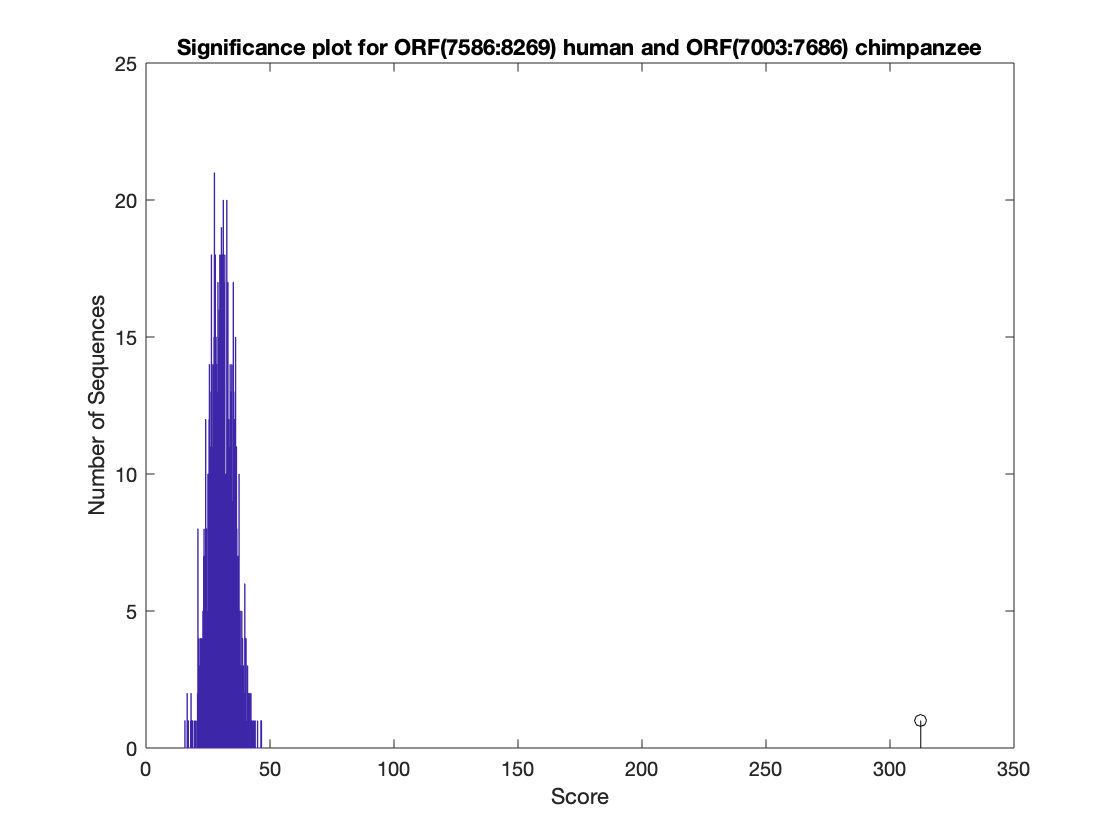

score = 312.4000

p_value = 0

ans = "ORF in position(7586:8269) in human is homologous to ORF in position (7003:7686) in chimpanzee"

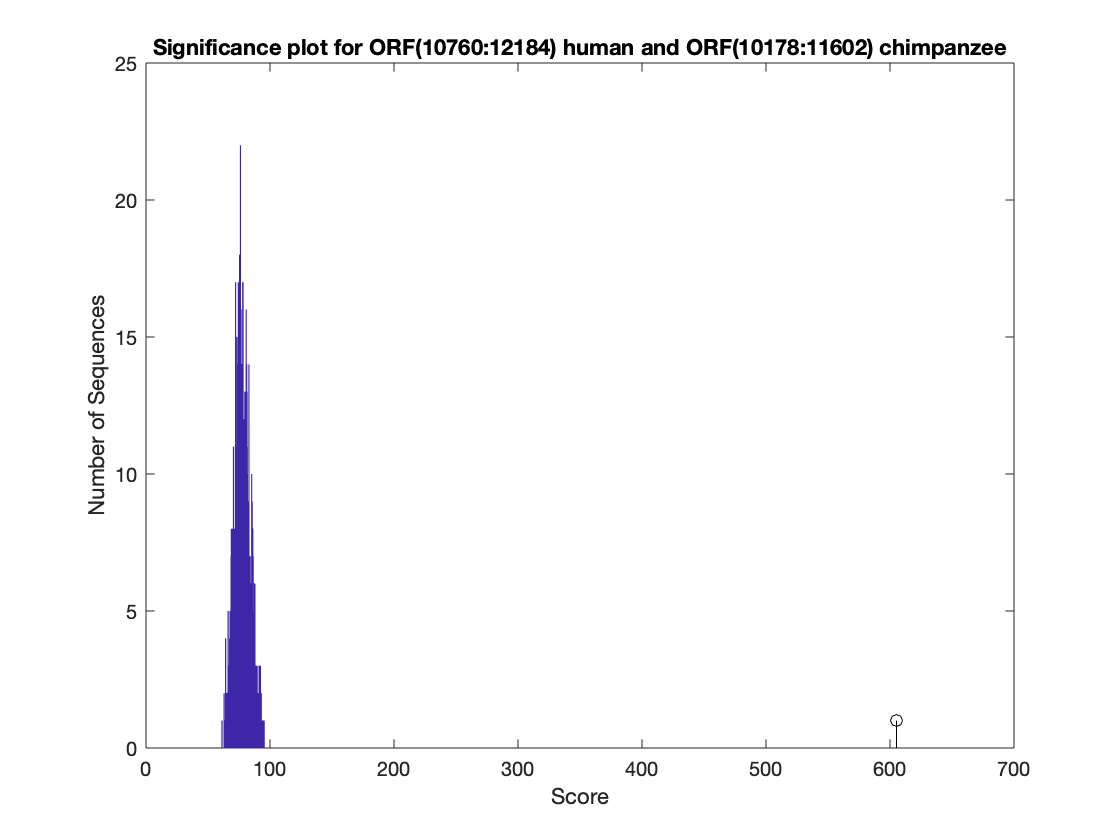

score = 605.2000

p_value = 0

ans = "ORF in position(10760:12184) in human is homologous to ORF in position (10178:11602) in chimpanzee"

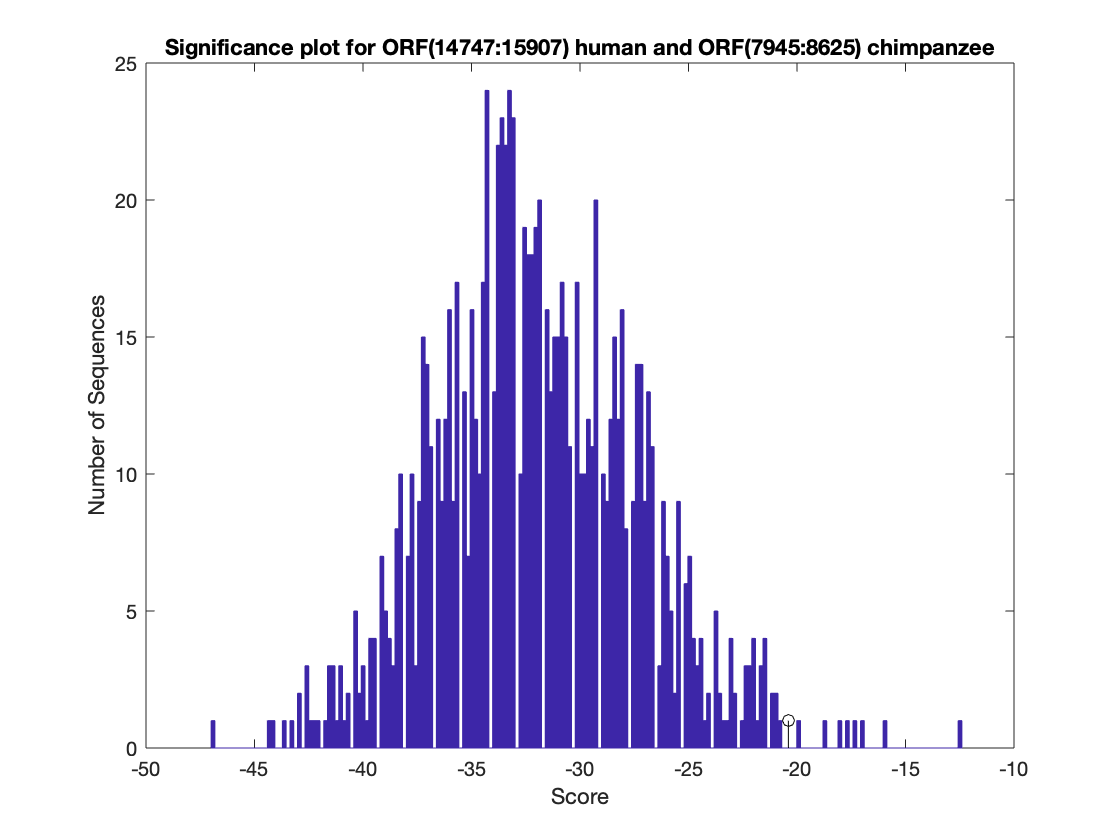

score = -20.4000

p_value = 0.0080

ans = "ORF in position(14747:15907) in human is homologous to ORF in position (7945:8625) in chimpanzee"

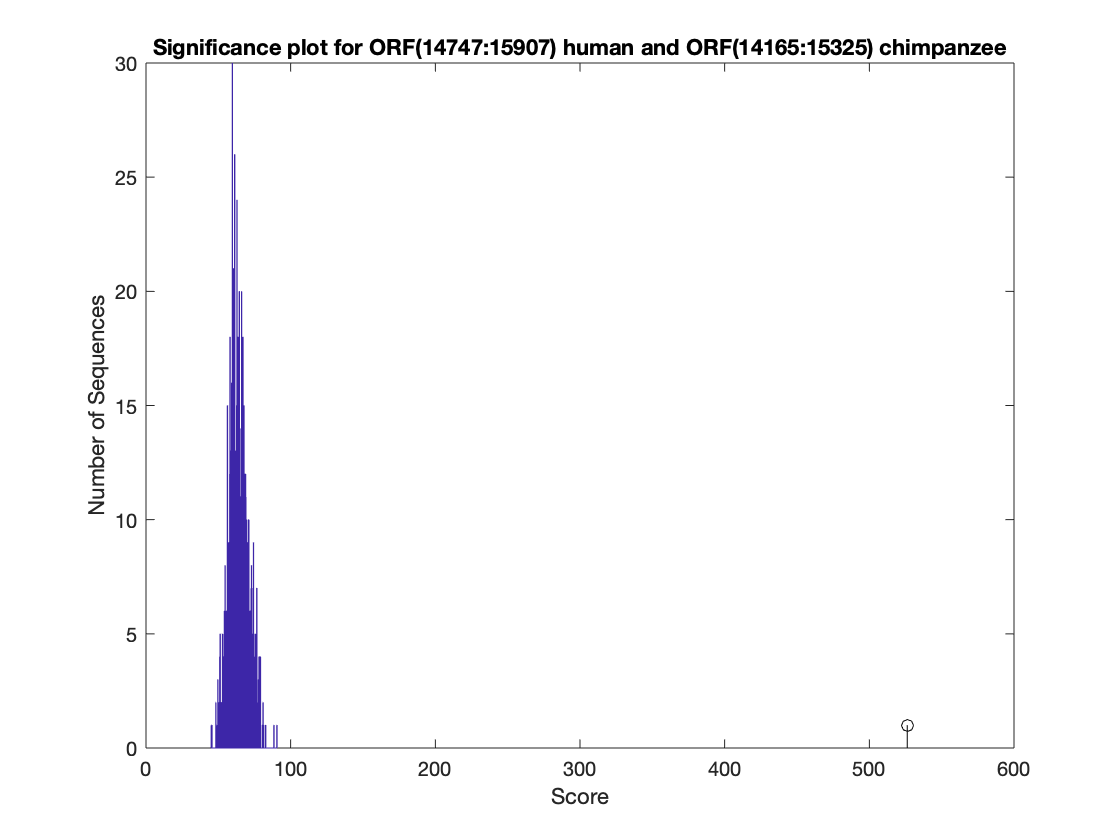

score = 526.2000

p_value = 0

ans = "ORF in position(14747:15907) in human is homologous to ORF in position (14165:15325) in chimpanzee"

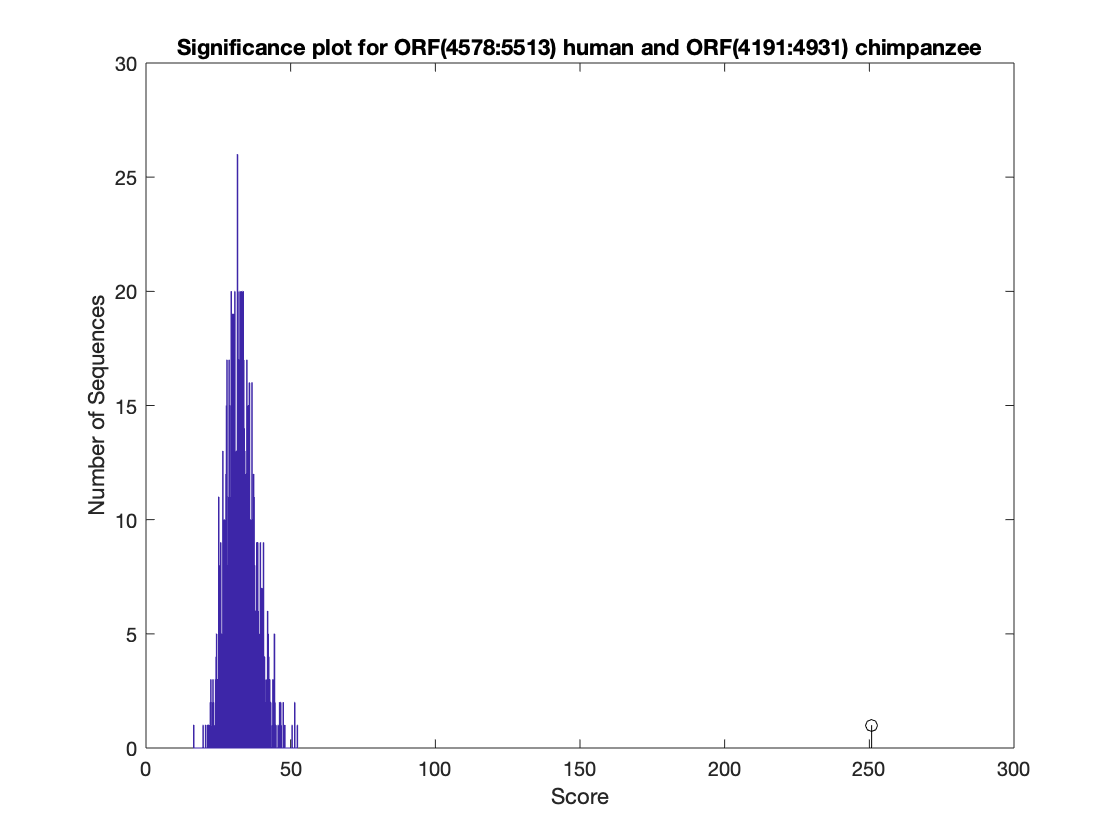

score = 250.8000

p_value = 0

ans = "ORF in position(4578:5513) in human is homologous to ORF in position (4191:4931) in chimpanzee"

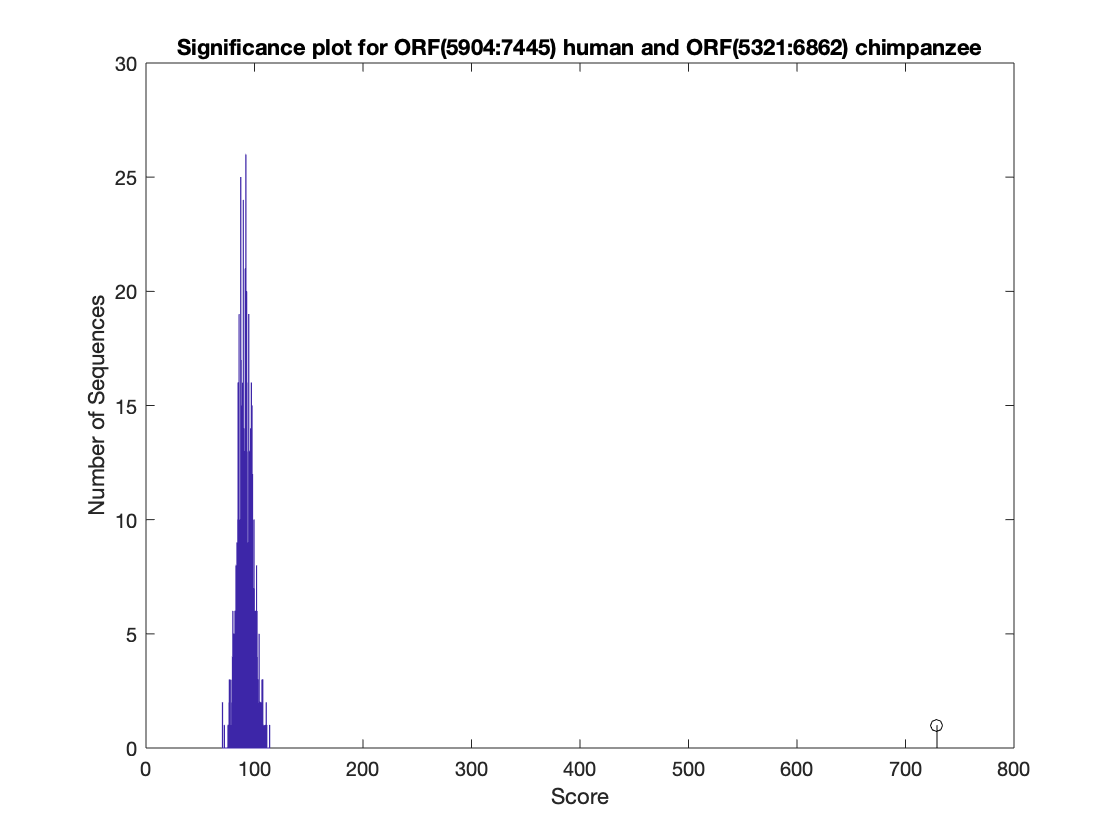

score = 729

p_value = 0

ans = "ORF in position(5904:7445) in human is homologous to ORF in position (5321:6862) in chimpanzee"

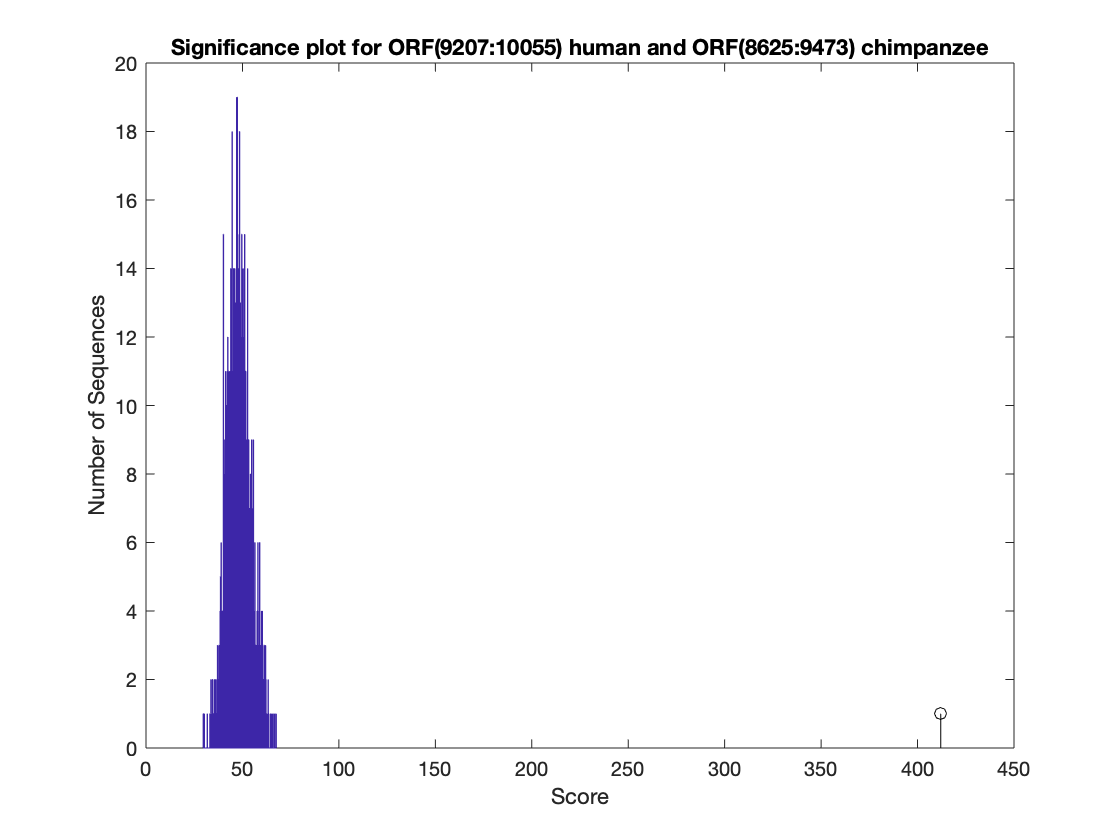

score = 412

p_value = 0

ans = "ORF in position(9207:10055) in human is homologous to ORF in position (8625:9473) in chimpanzee"

for i=1:total_combinations
    h = scores(i,1);
    c = scores(i,2);
    score = scores(i,3);
    human_protein = char(h_aminoacid(h,1));
    chimp_protein = char(aminoacid(c,1));
    n = 1000;
    globalscores = zeros(n,1);
    chimpLen = length(chimp_protein);
    for j = 1:n
        perm = randperm(chimpLen);
        globalscores(j) = nwalign(human_protein,chimp_protein(perm),'scoringmatrix','blosum30','gapopen',5,'extendgap',5);
    end
    p_value = length(find(globalscores >= score)) / 1000;
    if (p_value < 0.01)
        figure
        buckets = ceil(n/5);
        hist(globalscores,buckets)
        hold on;
        stem(score,1,'k')
        xlabel('Score'); ylabel('Number of Sequences');
         titleStr = strcat('Significance plot for ORF(' ,h_aminoacid(h,2),':',h_aminoacid(h,3), ...
             ') human and ORF(',aminoacid(c,2),':',aminoacid(c,3), ') chimpanzee');
        title(titleStr);
        hold off;
        score
        p_value
        strcat('ORF in position(' ,h_aminoacid(h,2),':',h_aminoacid(h,3), ...
              ') in human is homologous to ORF in position (',aminoacid(c,2),':',aminoacid(c,3), ') in chimpanzee')
    end
end